# Robotics 2 - Final Exam  - July 11, 2018

## Exercise 1

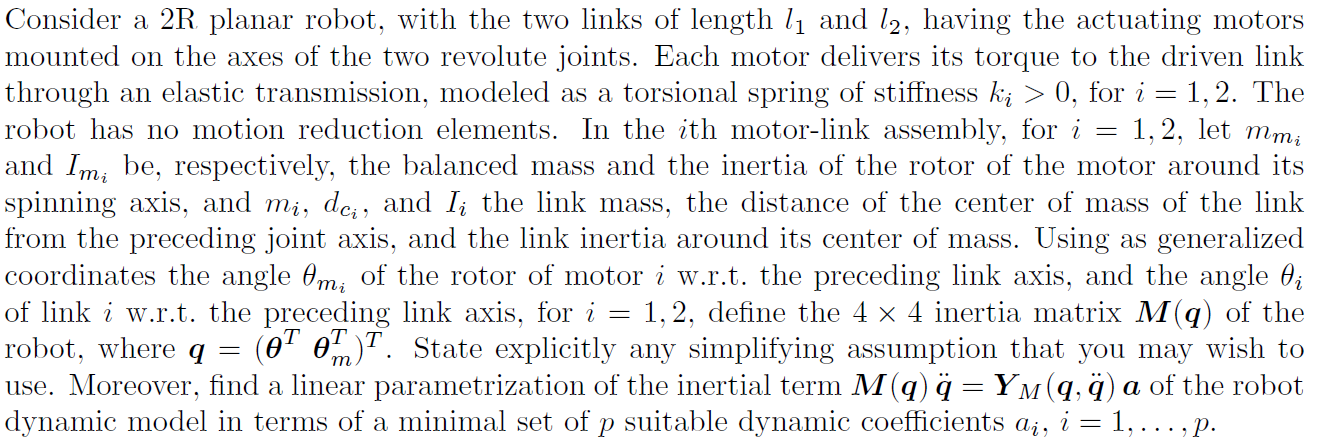

clear ;clc;
sigma = [0,0]; % 0: Revolute, 1:Prismatic
n = length(sigma);

% Link parameters
q = sym('q', [1,n]).' ;
qd = sym('qd', [1,n]).' ;
l = sym('l', [1,n]).' ;
m = sym('m', [1,n]).' ;
d = sym('d', [1,n]).' ;
I = sym('I', [1,n]).' ;
qdd = sym('qdd',[1,n]).'

$$qdd = \left(\begin{array}{c} {\mathrm{qdd}}_{1}\\ {\mathrm{qdd}}_{2} \end{array}\right)$$


% Motor parameters
qm = sym('qm', [1,n]).' ;
qdm = sym('qdm', [1,n]).' ;
lm = sym('lm', [1,n]).' ;
mm = sym('mm', [1,n]).' ;
dm = sym('dm', [1,n]).' ;
Im = sym('Im', [1,n]).' ;
qddm = sym('qddm',[1,n]).'

$$qddm = \left(\begin{array}{c} {\mathrm{qddm}}_{1}\\ {\mathrm{qddm}}_{2} \end{array}\right)$$

dm = sym('dm', [1,n])

$$dm = \left(\begin{array}{cc} {\mathrm{dm}}_{1} & {\mathrm{dm}}_{2} \end{array}\right)$$


[dhTable, Msubs, dynParams, a]  = getRR_Robot()

sigma =      0
     0


$$qd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2} \end{array}\right)$$

============= Link 1
============= Link 2


$$U = \left(\begin{array}{c} d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$U = \left(\begin{array}{c} d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)\\ g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right) \end{array}\right)$$

>> Getting dynamic coefficients. Might take a while...
Only one term in the list of terms


params1term = 1×2 logical array
   0   1


% Just replace to distinguish l from I (Inertia)
%dhTable = subs(dhTable,  sym('l', [1,n]).', L)

dhTable

Undefined function or variable 'dhTable'.

### Computation of Kinetic Energy

[KE_Links , Tlinks] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)
[KE_Motors , Tmotors] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,1,qdm)

### Computation of Inertia matrix

KE_Total = KE_Links + KE_Motors
M = getInertiaMatrixFromKE(KE_Total,[qd;qdm])

[Msubs, dynamicParamsReturn, a] = getDynamicParameters(M,[q;qm],[])

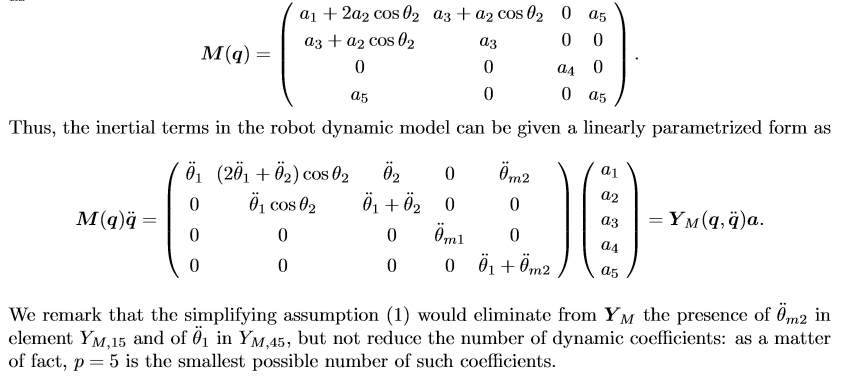

###  Computation of Linear Parametrization

YM = getLinearParametrization(Msubs, [qdd;qddm], a)

## Exercise 2

**This is incomplete!!! The SNS algoruth has to be corrected and completed.**

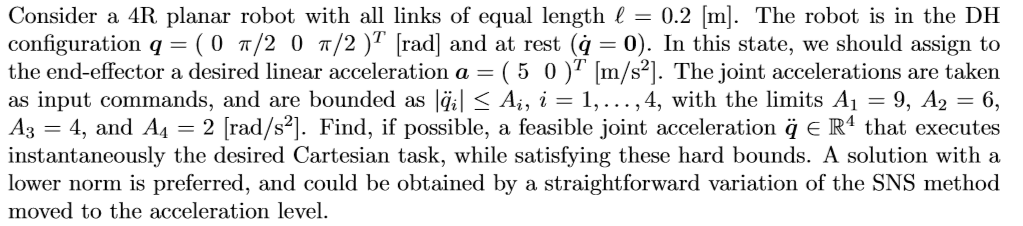

disp('** Exercise 2')
clear ;clc;
sigma = [0,0,0,0]; % 0: Revolute, 1:Prismatic
n = length(sigma);

% Link parameters
q = sym('q', [1,n]).' ;
qd = sym('qd', [1,n]).' ;
l = sym('l') ;
m = sym('m', [1,n]).' ;
d = sym('d', [1,n]).' ;
I = sym('I', [1,n]).' ;
qdd = sym('qdd',[1,n]).'

dhTable = [0, l, 0, q(1);
           0, l, 0, q(2);
           0, l, 0, q(3);
           0, l, 0, q(4)]

q0 = [0, pi/2, 0, pi/2].'; % initial configuration.
qd0 = [0,0,0,0].'; % Initial velocity at rest.


% Calculate the Jacobian (Rotational)
[Jp, Jo] = getJacobian(dhTable,sigma,'alpha')
%Jac = [Jp;Jo]
%Eliminate the zero rows, which represent the unused variables
Jp = Jp(~all(Jp == 0,2),:)

J = subs(Jp, [q; l], [q0 ; 0.2])

SNS_sol(J, xdd, A)

% Acceleration limits
A = [9,6,4,2];

% SNS (Saturation on Null Space)
xdd= [5,0].'
qddPS = eval(pinv(J))*xdd
maxvalue = 1
qddstar = qddPS
qdd_sns = qddPS
while maxvalue > 0
    [maxvalue, maxindex] = max(abs(qddstar)-abs(A')) % The positive values are violating the limit. We take the highest one.
    if (maxvalue > 0) % if there is an exceeding value
        s = A(1)/qddstar(maxindex)    
        %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
        %Same as 
        xdot_sns  = xdd - abs(J(:,maxindex)*A(maxindex));
        Jtemp = J
        Jtemp(:,maxindex) = [];
        qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
        qdd_sns = [qdot_components(1:maxindex-1), A(maxindex), qdot_components(maxindex:end)]
        qddstar = qdd_sns;
    else
        disp("[INFO] No values are exceeding the limits.")
        disp('Result:')
        qddstar
    end
end

## Exercise 3